clc;clear;
n = 7;  % Cantidad de aleatorios a generar (para a y b)
mx= 3;  % Valor máximo/mínimo para el rango de aleatorios
Limite = 1; % Valor de límite a procesar.

# a) Generar n cantidad de números aleatorios enteros en el rango [0,mx]. (graficar con 'o')

# b) Generar n cantidad de números aleatorios enteros en el rango [-mx,0]. (graficar con 'o')

# c) Trazar línea (graficar) los datos del arreglo a, pero, modificando los valores menores a Limite pasándolos al entero superior). (Graficar con plot sin modificación, línea interpolada)

# d) Igual al punto c pero con los valores del arreglo b y aplicando la condición para valores mayores a Limite y convirtiento al entero inferior.

Octubre 11

% parte a. Generar aleatorios positivos
m1 = randi([0,mx],1,n)

m1 =      0     1     3     0     3     2     1


n2 = floor(n/2)

n2 = 3

x  = -n2:n2

x =     -3    -2    -1     0     1     2     3


plot(x,m1,'ko','LineWidth',3);grid;hold on
axis([min(x)-1,max(x)+1,-mx-2,mx+2]);

% parte b. Generar aleatorios negativos
m2 = randi([-mx,0],1,n)

m2 =     -1    -3    -2     0    -1    -1    -3


plot(x,m2,'ro','LineWidth',3);

% parte c. Modificar y graficar positivos
f = m1 <= Limite;
m1(f) = Limite+1;
plot(x,m1,'bsq-','LineWidth',2)

% parte d. Modificar y graficar negativos
f = m2 >= -Limite

f = 1×7 logical array
   1   0   0   1   1   1   0


m2a = (ones(1,n)*-2).*f

m2a =     -2     0     0    -2    -2    -2     0


m2b = m2.*(f==0)

m2b =      0    -3    -2     0     0     0    -3


m2c = m2a+m2b

m2c =     -2    -3    -2    -2    -2    -2    -3


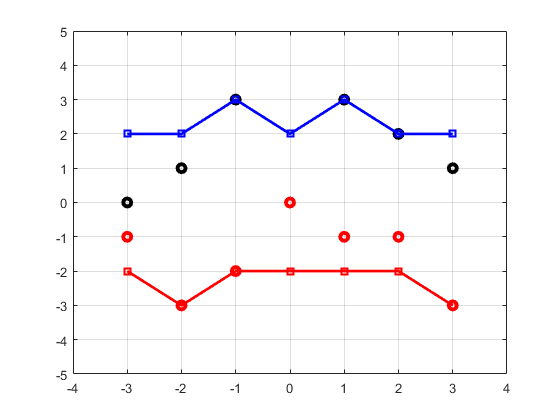

plot(x,m2c,'rsq-','LineWidth',2)
hold off;